# The Assignment Code

# Part A

## Solving Functions Using Numerical methods

We shall solve the following equations using various methods of numrical format i.e finding the roots of the equation.

### Number 1

#### Using Newton Raphsons  Formulae method

X = 2; %Initial Approximation 
ERR = 0.00005; %Error(depends on d.p required)
F = @(X) X - 2*sin(X); %FUNCTION
F_D = @(X) 1 - 2*cos(X); %functions derivative
X1 = X - (F(X)/F_D(X)); %Finding the next root
R_ERROR = abs(X1 - X); 
%%Using a while loop to repeat for n iterations
while R_ERROR > ERR
    X = X1;
    X1 = X - (F(X)/F_D(X))
    R_ERROR = abs(X1 - X);  
end

X1 = 1.8955

X1 = 1.8955

disp(["Final answer is:", num2str(X1)])

    "Final answer is:"    "1.8955"



#### Using Secant Method

x0 = 2; %Initial Approximation
x1 = 1.9; %Next Approximation
err = 0.00005;  
F = @(x) x - 2*sin(x);
T_ERROR = abs(x1 - x0);
while T_ERROR > err
    x2 = x1 - (F(x1)*(x1 - x0)) / (F(x1) - F(x0))
    T_ERROR = abs(x2 - x1);
    x0 = x1;
    x1 = x2;
end

x2 = 1.8957

x2 = 1.8955

x2 = 1.8955

disp(["The Final answer is" num2str(x2)])

    "The Final answer is"    "1.8955"



#### Bisection Method

a = 1; % Lower boundary
b = 3; % Upper boundary
ERR = 0.00005;

F = @(x) x - 2*sin(x);
%Checking for existance of root
if F(a)*F(b) > 0
    error('No root in the interval')
end

c = (a+b)/2; %Bisecting to find the next root
R_ERROR = abs(b-a);

%Using a while loop to repeat for many iterations
while R_ERROR > ERR
    if F(a)*F(c) < 0
        b = c;
    else
        a = c;
    end
    c_new = (a+b)/2;
    R_ERROR = abs(c_new - c);
    c = c_new
end

c = 1.5000

c = 1.7500

c = 1.8750

c = 1.9375

c = 1.9062

c = 1.8906

c = 1.8984

c = 1.8945

c = 1.8965

c = 1.8955

c = 1.8950

c = 1.8953

c = 1.8954

c = 1.8954

c = 1.8955


disp(["Final answer is: ", num2str(c)])

    "Final answer is: "    "1.8955"



#### Fixed Point Iteration

x0 = 2;%Initial Approximation                     
ERR = 0.00005;

g = @(x) 2*sin(x); %Rearraneged f(x), g(x) used to find x

x1 = g(x0);
R_ERROR = abs(x1 - x0);

while R_ERROR > ERR
    x0 = x1;
    x1 = g(x0)
    R_ERROR = abs(x1 - x0);
end

x1 = 1.9389

x1 = 1.8660

x1 = 1.9135

x1 = 1.8837

x1 = 1.9029

x1 = 1.8907

x1 = 1.8985

x1 = 1.8936

x1 = 1.8967

x1 = 1.8947

x1 = 1.8960

x1 = 1.8952

x1 = 1.8957

x1 = 1.8954

x1 = 1.8956

x1 = 1.8954

x1 = 1.8955

x1 = 1.8955

x1 = 1.8955


disp(["Final answer is: ", num2str(x1)])

    "Final answer is: "    "1.8955"



#### Number 2

Newton-Raphson Method

X = 3.5;                  
ERR = 0.00005;             

F = @(X) X^3 - 6*X^2 + 11*X - 6.1;
F_D = @(X) 3*X^2 - 12*X + 11;

X1 = X - F(X)/F_D(X);
R_ERROR = abs(X1 - X);

while R_ERROR > ERR
    X = X1;
    X1 = X - F(X)/F_D(X);
    R_ERROR = abs(X1 - X);
end

disp(["Final answer is: ", num2str(X1)])

    "Final answer is: "    "3.0467"



#### Secant Method

x0 = 3;                   
x1 = 2.8;                 
err = 0.00005;            

F = @(x) x^3 - 6*x^2 + 11*x - 6.1;
T_ERROR = abs(x1 - x0);

while T_ERROR > err
    x2 = x1 - (F(x1)*(x1 - x0)) / (F(x1) - F(x0));
    T_ERROR = abs(x2 - x1);
    x0 = x1;
    x1 = x2;
end

disp(["Final answer is: ", num2str(x2)])

    "Final answer is: "    "3.0467"



#### Bisection Method

a = 2.5;                    
b = 3.5;                    
ERR = 0.00005;

F = @(x) x^3 - 6*x^2 + 11*x - 6.1;

if F(a)*F(b) > 0
    error('No root in the interval')
end

c = (a+b)/2;
R_ERROR = abs(b-a);

while R_ERROR > ERR
    if F(a)*F(c) < 0
        b = c;
    else
        a = c;
    end
    c_new = (a+b)/2;
    R_ERROR = abs(c_new - c);
    c = c_new;
end

disp(["Final answer is: ", num2str(c)])

    "Final answer is: "    "3.0467"



#### Fixed Point Iteration

x0 = 3;                   
ERR = 0.00005;

g = @(x) (6.1 + 6*x^2 - x^3)/11;   % Rearranged form x = g(x)

x1 = g(x0);
R_ERROR = abs(x1 - x0);

while R_ERROR > ERR
    x0 = x1;
    x1 = g(x0);
    R_ERROR = abs(x1 - x0);
end

disp(["Final answer is: ", num2str(x1)])

    "Final answer is: "    "3.0465"



### Real World Application

#### Newton-Raphson Method (Projectile Motion)

tic
theta = 0.5;            
ERR = 5e-6;               
%Substituting given data from the question
v0 = 50; g = 9.81; R = 200;

F = @(theta) (v0^2 * sin(2*theta))/g - R;
F_D = @(theta) (2*v0^2 * cos(2*theta))/g;

theta1 = theta - F(theta)/F_D(theta);
R_ERROR = abs(theta1 - theta);

while R_ERROR > ERR
    theta = theta1;
    theta1 = theta - F(theta)/F_D(theta)
    R_ERROR = abs(theta1 - theta);
end

theta1 = 0.4512

theta1 = 0.4512

theta1 = 0.4512


disp(["Newton-Raphson: Launch angle = ", num2str(rad2deg(theta1))])

    "Newton-Raphson: Launch angle = "    "25.8511"



timetaken_NR_ = toc 

timetaken_NR_ = 0.0927

### Secant Method (Projectile Motion)

tic
theta0 = 0.4;              
theta1 = 0.6;              
err = 5e-6;
%Substituting given data from the question
F = @(theta) (v0^2 * sin(2*theta))/g - R;
T_ERROR = abs(theta1 - theta0);

while T_ERROR > err
    theta2 = theta1 - (F(theta1)*(theta1 - theta0)) / (F(theta1) - F(theta0))
    T_ERROR = abs(theta2 - theta1);
    theta0 = theta1;
    theta1 = theta2;
end

theta2 = 0.4628

theta2 = 0.4482

theta2 = 0.4512

theta2 = 0.4512

theta2 = 0.4512

disp(["Secant Method: Launch angle = ", num2str(rad2deg(theta2))])

    "Secant Method: Launch angle = "    "25.8511"



time_taken_Secant = toc

time_taken_Secant = 0.0714

#### Bisection Method (Projectile Motion)

tic
a = 0.2;                    
b = 0.6;                    
ERR = 5e-6;
%Substituting given data from the question
v0 = 50; g = 9.81; R = 200;
F = @(theta) (v0^2 * sin(2*theta))/g - R;

if F(a)*F(b) > 0
    error('No root in the interval')
end

c = (a+b)/2;
R_ERROR = abs(b-a);

while R_ERROR > ERR
    if F(a)*F(c) < 0
        b = c;
    else
        a = c;
    end
    c_new = (a+b)/2;
    R_ERROR = abs(c_new - c);
    c = c_new;
end

disp(["Bisection Method: Launch angle = ", num2str(rad2deg(c))])

    "Bisection Method: Launch angle = "    "25.8511"



time_taken_Bisection = toc

time_taken_Bisection = 0.0799

#### Fixed Point Iteration (Projectile Motion)

tic
theta0 = 0.4;               
ERR = 5e-6;
%Substituting given data from the question
v0 = 50; g = 9.81; R = 200;

% Rearranged form
gfun = @(theta) 0.5 * asin((R*g)/(v0^2));

theta3 = gfun(theta0);
R_ERROR = abs(theta3 - theta0);

while R_ERROR > ERR
    theta0 = theta3;
    theta3 = gfun(theta0);
    R_ERROR = abs(theta3 - theta0);
end

disp(["Fixed Point Iteration: Launch angle = ", num2str(rad2deg(theta3))])

    "Fixed Point Iteration: Launch angle = "    "25.8511"



time_taken_FPI = toc

time_taken_FPI = 0.0446

Method = {'Newton-Raphson'; 'Secant'; 'Bisection'; 'Fixed Point Iterations'};
Computational_Time = [timetaken_NR_; time_taken_Secant; time_taken_Bisection; time_taken_FPI];
Final_Answers = [rad2deg(theta1); rad2deg(theta2); rad2deg(c); rad2deg(theta3)];

Results_Table = table(Method, Final_Answers, Computational_Time)

Results_Table = 4×3 table
              Method              Final_Answers    Computational_Time
    __________________________    _____________    __________________

    {'Newton-Raphson'        }       25.851             0.092736     
    {'Secant'                }       25.851             0.071366     
    {'Bisection'             }       25.851             0.079882     
    {'Fixed Point Iterations'}       25.851             0.044615     


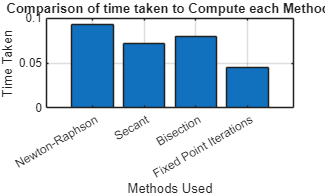


%Plots
figure
bar(Method,Results_Table.Computational_Time)
grid on
xlabel('Methods Used'); 
ylabel('Time Taken');
title('Comparison of time taken to Compute each Method ');

# Part B

## Solving Ordinary Differential Equations with Numerical methods

We shall solve the ordinary differentail equations using various methods.

### Number 1

#### Using Eulers method

tic
%DATA INPUT
x = 0;
h = 0.2;
y = 1;
x_l = 1.8;
y_exact = 0.5*(sin(x) - cos(x)) + 1.5*exp(-x);
y_d = sin(x) - y;
y_1 = y + h*y_d;

X = [];
Y = [];
Y_exact = [];
Error = [];

X(end+1,1) = x;
Y(end+1,1) = y;
Y_exact(end+1,1) = y_exact;
Error(end+1,1) = abs(y_exact - y);

%USING A WHILE LOOP TO REPEAT THE PROCESS FOR VARIOUS X VALUES
while x < x_l
    x = x + h;
    y = y_1;
    y_d = sin(x) - y;
    y_1 = y + h*y_d;
    y_exact = 0.5*(sin(x) - cos(x)) + 1.5*exp(-x);
    X(end+1,1) = x;
    Y(end+1,1) = y;
    Y_exact(end+1,1) = y_exact;
    Error(end+1,1) = abs(y_exact - y);
end
Results_Eulers1 = table(X, Y, Y_exact, Error)

Results_Eulers1 = 11×4 table
     X        Y       Y_exact     Error  
    ___    _______    _______    ________

      0          1          1           0
    0.2        0.8     0.8374    0.037398
    0.4    0.67973    0.73966    0.059925
    0.6    0.62167    0.69287      0.0712
    0.8    0.61027    0.68432    0.074053
      1    0.63168     0.7024     0.07072
    1.2    0.67364    0.73663    0.062991
    1.4    0.72532    0.77764    0.052316
    1.6    0.77735    0.81723    0.039885
    1.8    0.82179    0.84847    0.026681
      2     0.8522    0.86573    0.013522


timetaken_Eulers1 = toc

timetaken_Eulers1 = 0.3873

#### Using Heuns Method

tic
%DATA INPUT
x = 0;
h = 0.2;
y = 1;
x_l = 1.8;
y_d = sin(x) - y;
a = x + h;
b = y + h*y_d;
ab = sin(a) - b;
y_exact = 0.5*(sin(x) - cos(x)) + 1.5*exp(-x);
y_1 = y + 0.5*h*(y_d + ab);

X_H = [];
Y_H = [];
Y_Exact_H = [];
Error_H = [];

X_H(end+1,1) = x;
Y_H(end+1,1) = y;
Y_Exact_H(end+1,1) = y_exact;
Error_H(end+1,1) = abs(y_exact - y);

%USING A WHILE LOOP TO REPEAT THE PROCESS FOR VARIOUS X VALUES
while x <= x_l
    x = x + h;
    y = y_1;
    y_d = sin(x) - y;
    a = x + h;
    b = y + h*y_d;
    ab = sin(a) - b;
    y_1 = y + 0.5*h*(y_d + ab);
    y_exact = 0.5*(sin(x) - cos(x)) + 1.5*exp(-x);
    
    X_H(end+1,1) = x;
    Y_H(end+1,1) = y;
    Y_Exact_H(end+1,1) = y_exact;
    Error_H(end+1,1) = abs(y_exact - y);
end
Results_Heuns1 = table(X_H, Y_H, Y_Exact_H, Error_H)

Results_Heuns1 = 11×4 table
    X_H      Y_H      Y_Exact_H     Error_H  
    ___    _______    _________    __________

      0          1           1              0
    0.2    0.83987      0.8374      0.0024694
    0.4    0.74353     0.73966      0.0038675
    0.6    0.69731     0.69287      0.0044384
    0.8     0.6887     0.68432      0.0043825
      1    0.70627      0.7024      0.0038666
    1.2    0.73966     0.73663      0.0030311
    1.4    0.77963     0.77764      0.0019951
    1.6    0.81809     0.81723     0.00086007
    1.8    0.84819     0.84847     0.00028758
      2    0.86435     0.86573      0.0013753


timetaken_Heuns1 = toc

timetaken_Heuns1 = 0.2267

#### Using Runge Kutta method

tic
%DATA INPUT
h = 0.2;
a = 0;
b = 2;
c = 1;

% list the values of x 
x = (a:h:b);
y(1) = c;
y_exact = 0.5*(sin(x) - cos(x)) + 1.5*exp(-x);
func = @(x,y) sin(x) - y;

%VALUES OF K ARE FOUND USING FOR LOOP
for i=1:(length(x)-1)
    k1 = h.*func(x(i),y(i));
    k2 = h.*func(x(i)+h/2,y(i)+k1/2);
    k3 = h.*func(x(i)+h/2,y(i)+k2/2);
    k4 = h.*func(x(i)+h,y(i)+k3);
    k = (1/6).*(k1+ (2*k2) + (2*k3) +k4);
    y(i+1) = y(i)+ k;
end
%Tabulate data
y_exact = transpose(y_exact);
y1 = transpose(y);
x1 = transpose(x);
Error_R = abs(y1-y_exact);
Results_Runge1 = table(x1,y1,y_exact,Error_R)

Results_Runge1 = 11×4 table
    x1       y1       y_exact     Error_R  
    ___    _______    _______    __________

      0          1          1             0
    0.2     0.8374     0.8374    4.7039e-06
    0.4    0.73967    0.73966    7.4596e-06
    0.6    0.69288    0.69287      8.73e-06
    0.8    0.68433    0.68432    8.8872e-06
      1    0.70241     0.7024    8.2337e-06
    1.2    0.73664    0.73663    7.0173e-06
    1.4    0.77764    0.77764     5.443e-06
    1.6    0.81724    0.81723     3.681e-06
    1.8    0.84848    0.84847    1.8725e-06
      2    0.86573    0.86573    1.3406e-07


timetaken_Runge1 = toc

timetaken_Runge1 = 0.3777

### Number 2

#### Using Eulers method

tic
% DATA INPUT
x = 0;         
h = 0.2;       
y = 1;         
x_l = 2.4;     

y_exact = (2*sin(3*x) - 3*cos(3*x))/13 + (16/13)*exp(-2*x);
y_d = sin(3*x) - 2*y;
y_1 = y + h*y_d;

X = [];
Y = [];
Y_exact = [];
Error = [];

X(end+1,1) = x;
Y(end+1,1) = y;
Y_exact(end+1,1) = y_exact;
Error(end+1,1) = abs(y_exact - y);

% WHILE LOOP for Euler
while x < x_l
    x = x + h;
    y = y_1;
    y_d = sin(3*x) - 2*y;
    y_1 = y + h*y_d;
    y_exact = (2*sin(3*x) - 3*cos(3*x))/13 + (16/13)*exp(-2*x);

    X(end+1,1) = x;
    Y(end+1,1) = y;
    Y_exact(end+1,1) = y_exact;
    Error(end+1,1) = abs(y_exact - y);
end
Results_Eulers_2 = table(X, Y, Y_exact, Error)

Results_Eulers_2 = 13×4 table
     X        Y         Y_exact        Error  
    ___    ________    __________    _________

      0           1             1            0
    0.2         0.6       0.72142      0.12142
    0.4     0.47293       0.61279      0.13986
    0.6     0.47016       0.57295      0.10279
    0.8     0.47687       0.52257     0.045705
      1     0.42121       0.41674    0.0044766
    1.2     0.28095       0.25052     0.030435
    1.4    0.080067      0.053892     0.026176
    1.6    -0.12627      -0.12328    0.0029955
    1.8      -0.275      -0.23173     0.043273
      2    -0.31955      -0.24202     0.077529
    2.2    -0.24761      -0.15624      0.09137
    2.4    -0.08626    -0.0081571     0.078103


timetaken_Eulers_2 = toc

timetaken_Eulers_2 = 0.2442

#### Using Heuns Method

tic
% DATA INPUT
x = 0;
h = 0.2;
y = 1;
x_l = 2.4;

y_d = sin(3*x) - 2*y;
a = x + h;
b = y + h*y_d;
ab = sin(3*a) - 2*b;
y_exact = (2*sin(3*x) - 3*cos(3*x))/13 + (16/13)*exp(-2*x);
y_1 = y + 0.5*h*(y_d + ab);

X_H = [];
Y_H = [];
Y_Exact_H = [];
Error_H = [];

X_H(end+1,1) = x;
Y_H(end+1,1) = y;
Y_Exact_H(end+1,1) = y_exact;
Error_H(end+1,1) = abs(y_exact - y);

% WHILE LOOP for Heun
while x < x_l
    x = x + h;
    y = y_1;
    y_d = sin(3*x) - 2*y;
    a = x + h;
    b = y + h*y_d;
    ab = sin(3*a) - 2*b;
    y_1 = y + 0.5*h*(y_d + ab);
    y_exact = (2*sin(3*x) - 3*cos(3*x))/13 + (16/13)*exp(-2*x);

    X_H(end+1,1) = x;
    Y_H(end+1,1) = y;
    Y_Exact_H(end+1,1) = y_exact;
    Error_H(end+1,1) = abs(y_exact - y);
end
Results_Heuns_2 = table(X_H, Y_H, Y_Exact_H, Error_H)

Results_Heuns_2 = 13×4 table
    X_H       Y_H       Y_Exact_H      Error_H 
    ___    _________    __________    _________

      0            1             1            0
    0.2      0.73646       0.72142     0.015049
    0.4      0.62788       0.61279     0.015088
    0.6      0.58026       0.57295    0.0073097
    0.8      0.52056       0.52257    0.0020164
      1      0.40862       0.41674    0.0081186
    1.2      0.24208       0.25052    0.0084413
    1.4     0.050903      0.053892     0.002989
    1.6      -0.1173      -0.12328    0.0059821
    1.8     -0.21681      -0.23173     0.014917
      2     -0.22174      -0.24202     0.020285
    2.2     -0.13639      -0.15624     0.019852
    2.4    0.0053127    -0.0081571      0.01347


timetaken_Heuns_2 = toc

timetaken_Heuns_2 = 0.1751

#### Using Runge Kutta method

tic
% DATA INPUT
h = 0.2;
a = 0;
b = 2.4;
c = 1;          

% list the values of x 
x = (a:h:b);
y(1) = c;
y_exact = (2*sin(3*x) - 3*cos(3*x))/13 + (16/13)*exp(-2*x);
func = @(x,y) sin(3*x) - 2*y;

% FOR LOOP for RK4
for i=1:(length(x)-1)
    k1 = h.*func(x(i),y(i));
    k2 = h.*func(x(i)+h/2,y(i)+k1/2);
    k3 = h.*func(x(i)+h/2,y(i)+k2/2);
    k4 = h.*func(x(i)+h,y(i)+k3);
    k = (1/6).*(k1+ (2*k2) + (2*k3) +k4);
    y(i+1) = y(i)+ k;
end

% Tabulate results
y_exact = transpose(y_exact);
y1 = transpose(y);
x1 = transpose(x);
Error_R = abs(y1-y_exact);
Results_Runge_2 = table(x1,y1,y_exact,Error_R)

Results_Runge_2 = 13×4 table
    x1         y1         y_exact       Error_R  
    ___    __________    __________    __________

      0             1             1             0
    0.2       0.72153       0.72142    0.00011633
    0.4       0.61292       0.61279    0.00013406
    0.6       0.57305       0.57295    9.9843e-05
    0.8       0.52262       0.52257     4.993e-05
      1       0.41675       0.41674    1.0595e-05
    1.2       0.25051       0.25052    3.4937e-06
    1.4      0.053902      0.053892    9.8551e-06
    1.6      -0.12324      -0.12328    4.1903e-05
    1.8      -0.23165      -0.23173    7.7218e-05
      2      -0.24192      -0.24202    9.9614e-05
    2.2      -0.15615      -0.15624    9.8009e-05
    2.4    -0.0080868    -0.0081571    7.0327e-05


timetaken_Runge_2 = toc

timetaken_Runge_2 = 0.1582

### Practical Applicatoin

#### Using Eulers method

tic
% DATA INPUT
x = 0;          
h = 1;          
y = 200;        
x_l = 30;       

y_exact = 25 + (200-25)*exp(-0.1*x);
y_d = -0.1*(y - 25);
y_1 = y + h*y_d;

X = [];
Y = [];
Y_exact = [];
Error = [];

X(end+1,1) = x;
Y(end+1,1) = y;
Y_exact(end+1,1) = y_exact;
Error(end+1,1) = abs(y_exact - y);

% USING A WHILE LOOP
while x < x_l
    x = x + h;
    y = y_1;
    y_d = -0.1*(y - 25);
    y_1 = y + h*y_d;
    y_exact = 25 + (200-25)*exp(-0.1*x);

    X(end+1,1) = x;
    Y(end+1,1) = y;
    Y_exact(end+1,1) = y_exact;
    Error(end+1,1) = abs(y_exact - y);
end
Results_Eulers_Cooling = table(X, Y, Y_exact, Error)

Results_Eulers_Cooling = 31×4 table
    X       Y       Y_exact     Error 
    __    ______    _______    _______

     0       200       200           0
     1     182.5    183.35     0.84655
     2    166.75    168.28      1.5279
     3    152.57    154.64      2.0682
     4    139.82    142.31      2.4885
     5    128.34    131.14      2.8071
     6       118    121.04      3.0399
     7     108.7     111.9      3.2005
     8    100.33    103.63      3.3008
     9    92.799     96.15      3.3511
    10    86.019    89.379      3.3602
    11    79.917    83.252      3.3356
    12    74.425    77.709      3.2838
    13    69.483    72.693      3.2104
    14    65.034    68.154      3.1201
    15    61.031    64.048      3.0168


timetaken_Eulers_Cooling = toc

timetaken_Eulers_Cooling = 0.1830

timetaken_Eulers3 = toc

timetaken_Eulers3 = 0.1976

#### Using Heuns Method

tic
% DATA INPUT
x = 0;
h = 1;
y = 200;
x_l = 30;

y_d = -0.1*(y - 25);
a = x + h;
b = y + h*y_d;
ab = -0.1*(b - 25);
y_exact = 25 + (200-25)*exp(-0.1*x);
y_1 = y + 0.5*h*(y_d + ab);

X_H = [];
Y_H = [];
Y_Exact_H = [];
Error_H = [];

X_H(end+1,1) = x;
Y_H(end+1,1) = y;
Y_Exact_H(end+1,1) = y_exact;
Error_H(end+1,1) = abs(y_exact - y);

% USING A WHILE LOOP
while x < x_l
    x = x + h;
    y = y_1;
    y_d = -0.1*(y - 25);
    a = x + h;
    b = y + h*y_d;
    ab = -0.1*(b - 25);
    y_1 = y + 0.5*h*(y_d + ab);
    y_exact = 25 + (200-25)*exp(-0.1*x);

    X_H(end+1,1) = x;
    Y_H(end+1,1) = y;
    Y_Exact_H(end+1,1) = y_exact;
    Error_H(end+1,1) = abs(y_exact - y);
end
Results_Heuns_Cooling = table(X_H, Y_H, Y_Exact_H, Error_H)

Results_Heuns_Cooling = 31×4 table
    X_H     Y_H      Y_Exact_H    Error_H 
    ___    ______    _________    ________

     0        200        200             0
     1     183.38     183.35      0.028452
     2     168.33     168.28      0.051493
     3     154.71     154.64      0.069896
     4     142.39     142.31      0.084333
     5     131.24     131.14      0.095393
     6     121.15     121.04       0.10359
     7     112.01      111.9       0.10936
     8     103.75     103.63        0.1131
     9     96.265      96.15       0.11514
    10     89.495     89.379       0.11577
    11     83.368     83.252       0.11524
    12     77.823     77.709       0.11376
    13     72.805     72.693       0.11152
    14     68.263     68.154       0.10868
    15     64.153     64.048       0.10537


timetaken_Heuns_Cooling = toc

timetaken_Heuns_Cooling = 0.1875

#### Using Runge Kutta method

tic
% DATA INPUT
h = 1;
a = 0;
b = 30;       % final time
c = 200;      % initial temperature

% list the values of x 
x = (a:h:b);
y(1) = c;
y_exact = 25 + (200-25)*exp(-0.1*x);
func = @(x,y) -0.1*(y - 25);

% VALUES OF K ARE FOUND USING FOR LOOP
for i=1:(length(x)-1)
    k1 = h.*func(x(i),y(i));
    k2 = h.*func(x(i)+h/2,y(i)+k1/2);
    k3 = h.*func(x(i)+h/2,y(i)+k2/2);
    k4 = h.*func(x(i)+h,y(i)+k3);
    k = (1/6).*(k1+ (2*k2) + (2*k3) +k4);
    y(i+1) = y(i)+ k;
end

% Tabulate data
y_exact = transpose(y_exact);
y1 = transpose(y);
x1 = transpose(x);
Error_R = abs(y1-y_exact);
Results_Runge_Cooling = table(x1,y1,y_exact,Error_R)

Results_Runge_Cooling = 31×4 table
    x1      y1      y_exact     Error_R  
    __    ______    _______    __________

     0       200       200              0
     1    183.35    183.35     1.4344e-05
     2    168.28    168.28     2.5957e-05
     3    154.64    154.64     3.5231e-05
     4    142.31    142.31     4.2504e-05
     5    131.14    131.14     4.8074e-05
     6    121.04    121.04     5.2199e-05
     7     111.9     111.9     5.5104e-05
     8    103.63    103.63     5.6983e-05
     9     96.15     96.15     5.8005e-05
    10    89.379    89.379     5.8317e-05
    11    83.252    83.252     5.8044e-05
    12    77.709    77.709     5.7295e-05
    13    72.693    72.693     5.6163e-05
    14    68.155    68.154     5.4728e-05
    15    64.048    64.048     5.3057e-05


timetaken_Runge_Cooling = toc

timetaken_Runge_Cooling = 0.1527

Error_Table = table( ...
    Results_Eulers_Cooling.X, ...
    Results_Eulers_Cooling.Error, ...
    Results_Heuns_Cooling.Error_H, ...
    Results_Runge_Cooling.Error_R, ...
    'VariableNames', {'x','Euler_Error','Heun_Error','RK4_Error'})

Error_Table = 31×4 table
    x     Euler_Error    Heun_Error    RK4_Error 
    __    ___________    __________    __________

     0            0              0              0
     1      0.84655       0.028452     1.4344e-05
     2       1.5279       0.051493     2.5957e-05
     3       2.0682       0.069896     3.5231e-05
     4       2.4885       0.084333     4.2504e-05
     5       2.8071       0.095393     4.8074e-05
     6       3.0399        0.10359     5.2199e-05
     7       3.2005        0.10936     5.5104e-05
     8       3.3008         0.1131     5.6983e-05
     9       3.3511        0.11514     5.8005e-05
    10       3.3602        0.11577     5.8317e-05
    11       3.3356        0.11524     5.8044e-05
    12       3.2838        0.11376     5.7295e-05
    13       3.2104        0.11152     5.6163e-05
    14       3.1201        0.10868    


%TIME COMPARISON
Method = {'Euler'; 'Heun'; 'RK4'};
CompTime = [timetaken_Eulers_Cooling; timetaken_Heuns_Cooling; timetaken_Runge_Cooling];
Time_Table = table(Method, CompTime)

Time_Table = 3×2 table
     Method      CompTime
    _________    ________

    {'Euler'}    0.18296 
    {'Heun' }    0.18752 
    {'RK4'  }    0.15267 



%%PLOTS

figure;
plot(Results_Eulers_Cooling.X, Results_Eulers_Cooling.Y, 'r--o','LineWidth',1.2); 
hold on;
plot(Results_Heuns_Cooling.X_H, Results_Heuns_Cooling.Y_H, 'b--s','LineWidth',1.2);
plot(Results_Runge_Cooling.x1, Results_Runge_Cooling.y1, 'g--*','LineWidth',1.2);
legend('Euler','Heun','RK4','Exact');

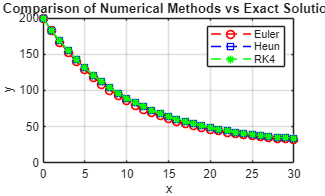

xlabel('x');
ylabel('y');
title('Comparison of Numerical Methods vs Exact Solution');
grid on;

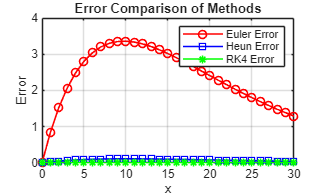



figure;
plot(Error_Table.x, Error_Table.Euler_Error, 'r-o','LineWidth',1.2); 
hold on;
plot(Error_Table.x, Error_Table.Heun_Error, 'b-s','LineWidth',1.2);
plot(Error_Table.x, Error_Table.RK4_Error, 'g-*','LineWidth',1.2);
legend('Euler Error','Heun Error','RK4 Error');
xlabel('x'); 
ylabel('Error');
title('Error Comparison of Methods');
grid on;